%% Vegyes Modulációs (BPSK-QPSK) Konvolúciós Kódolás Szimuláció
% Ez a szkript bemutatja az "Egyenlőtlen Hibavédelem" (UEP) módszereit.
% 3 rendszert versenyeztet: 
% 1. Tiszta QPSK
% 2. BPSK a széleken (Anchor effektus)
% 3. Elosztott BPSK szegmensek (Periodikus horgonyok a hibaterjedés ellen)

clear; clc; close all;

%% 1. Rendszer paraméterek
K = 7; % Kényszerhossz
poly = [171 133]; % Ipari standard polinomok
trellis = poly2trellis(K, poly);

dataLen = 994;          % Hasznos adatbitek száma
tailLen = K - 1;        % Tail (farok) bitek a regiszter kiürítéséhez
% R=1/2 miatt a kódolt bitszám pontosan a duplája:
codedLen = (dataLen + tailLen) * 2; % 1000 * 2 = 2000 kódolt bit

snr_dB_array = 0:0.5:4.5; % SNR tartomány
max_keret = 1000;         % Szimulált keretek SNR pontonként

% Eredménytárolók
ber_qpsk  = zeros(size(snr_dB_array));
ber_edge  = zeros(size(snr_dB_array));
ber_distr = zeros(size(snr_dB_array));

fprintf('--- Szimuláció indítása: Különböző UEP elrendezések ---\n');

--- Szimuláció indítása: Különböző UEP elrendezések ---


fprintf('Kódolt kerethossz: %d bit (Mindenhol 400 BPSK és 1600 QPSK bittel gazdálkodunk!)\n\n', codedLen);

Kódolt kerethossz: 2000 bit (Mindenhol 400 BPSK és 1600 QPSK bittel gazdálkodunk!)




for snr_idx = 1:length(snr_dB_array)
    snr = snr_dB_array(snr_idx);
    hiba_qpsk = 0; hiba_edge = 0; hiba_distr = 0;
    
    nv = 10^(-snr/10); % Zajteljesítmény
    
    for k = 1:max_keret
        %% --- ADATGENERÁLÁS ÉS KÓDOLÁS (Közös mind a 3 rendszerhez) ---
        data = randi([0 1], dataLen, 1);
        dataWithTail = [data; zeros(tailLen, 1)]; 
        codedData = convenc(dataWithTail, trellis); % 2000 bit
        
        %% --- 1. RENDSZER: TISZTA QPSK (REFERENCIA) ---
        cD_qpsk = reshape(codedData, 2, [])';
        tx_qpsk = pskmod(bi2de(cD_qpsk, "left-msb"), 4, pi/4);
        rx_qpsk = awgn(tx_qpsk, snr, 'measured');
        llr_qpsk_pairs = pskdemod(rx_qpsk, 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        
        dec_qpsk_full = vitdec(llr_qpsk_pairs(:), trellis, 100, 'term', 'unquant');
        hiba_qpsk = hiba_qpsk + biterr(data, dec_qpsk_full(1:dataLen));
        
        %% --- 2. RENDSZER: SZÉLEKEN BPSK (A te eredeti ötleted) ---
        % Felosztás: 200 BPSK | 1600 QPSK | 200 BPSK
        tx_edge = [ pskmod(codedData(1:200), 2, 0); ...
                    pskmod(bi2de(reshape(codedData(201:1800), 2, [])', "left-msb"), 4, pi/4); ...
                    pskmod(codedData(1801:2000), 2, 0) ];
                
        rx_edge = awgn(tx_edge, snr, 'measured');
        
        % Demoduláció szegmensenként
        llr_edge_1 = pskdemod(rx_edge(1:200), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        llr_edge_2 = pskdemod(rx_edge(201:1000), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv); % 800 szimbólum = 1600 bit
        llr_edge_3 = pskdemod(rx_edge(1001:1200), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        
        llr_edge_stream = [llr_edge_1; llr_edge_2(:); llr_edge_3];
        dec_edge_full = vitdec(llr_edge_stream, trellis, 100, 'term', 'unquant');
        hiba_edge = hiba_edge + biterr(data, dec_edge_full(1:dataLen));
        
        %% --- 3. RENDSZER: ELOSZTOTT BPSK (A továbbfejlesztett ötlet) ---
        % Ugyanannyi (400) BPSK bitet használunk, de 5 blokkba osztva:
        % 80 BPSK | 400 QPSK | 80 BPSK | 400 QPSK | 80 BPSK | 400 QPSK | 80 BPSK | 400 QPSK | 80 BPSK
        
        % Moduláció feldarabolva
        tx_d1 = pskmod(codedData(1:80), 2, 0);
        tx_d2 = pskmod(bi2de(reshape(codedData(81:480), 2, [])', "left-msb"), 4, pi/4);
        tx_d3 = pskmod(codedData(481:560), 2, 0);
        tx_d4 = pskmod(bi2de(reshape(codedData(561:960), 2, [])', "left-msb"), 4, pi/4);
        tx_d5 = pskmod(codedData(961:1040), 2, 0);
        tx_d6 = pskmod(bi2de(reshape(codedData(1041:1440), 2, [])', "left-msb"), 4, pi/4);
        tx_d7 = pskmod(codedData(1441:1520), 2, 0);
        tx_d8 = pskmod(bi2de(reshape(codedData(1521:1920), 2, [])', "left-msb"), 4, pi/4);
        tx_d9 = pskmod(codedData(1921:2000), 2, 0);
        
        tx_distr = [tx_d1; tx_d2; tx_d3; tx_d4; tx_d5; tx_d6; tx_d7; tx_d8; tx_d9];
        rx_distr = awgn(tx_distr, snr, 'measured');
        
        % Demoduláció (szimbólum indexek: 80 BPSK, 200 QPSK szimbólumok váltakozva)
        ll1 = pskdemod(rx_distr(1:80), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll2 = pskdemod(rx_distr(81:280), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll3 = pskdemod(rx_distr(281:360), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll4 = pskdemod(rx_distr(361:560), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll5 = pskdemod(rx_distr(561:640), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll6 = pskdemod(rx_distr(641:840), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll7 = pskdemod(rx_distr(841:920), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll8 = pskdemod(rx_distr(921:1120), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll9 = pskdemod(rx_distr(1121:1200), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        
        llr_distr_stream = [ll1; ll2(:); ll3; ll4(:); ll5; ll6(:); ll7; ll8(:); ll9];
        dec_distr_full = vitdec(llr_distr_stream, trellis, 100, 'term', 'unquant');
        hiba_distr = hiba_distr + biterr(data, dec_distr_full(1:dataLen));
    end
    
    % BER számítása
    ber_qpsk(snr_idx)  = hiba_qpsk / (max_keret * dataLen);
    ber_edge(snr_idx)  = hiba_edge / (max_keret * dataLen);
    ber_distr(snr_idx) = hiba_distr / (max_keret * dataLen);
    
    fprintf('SNR: %2.1f dB | Tiszta: %e | Szélek: %e | Elosztott: %e\n', ...
            snr, ber_qpsk(snr_idx), ber_edge(snr_idx), ber_distr(snr_idx));
end

SNR: 0.0 dB | Tiszta: 1.485553e-01 | Szélek: 1.220966e-01 | Elosztott: 1.088270e-01
SNR: 0.5 dB | Tiszta: 8.227163e-02 | Szélek: 6.703722e-02 | Elosztott: 6.068913e-02
SNR: 1.0 dB | Tiszta: 3.826861e-02 | Szélek: 3.318109e-02 | Elosztott: 2.773541e-02
SNR: 1.5 dB | Tiszta: 1.542455e-02 | Szélek: 1.182394e-02 | Elosztott: 1.102515e-02
SNR: 2.0 dB | Tiszta: 5.470825e-03 | Szélek: 4.394366e-03 | Elosztott: 3.647887e-03
SNR: 2.5 dB | Tiszta: 1.418511e-03 | Szélek: 1.049296e-03 | Elosztott: 1.262575e-03
SNR: 3.0 dB | Tiszta: 3.480885e-04 | Szélek: 2.917505e-04 | Elosztott: 3.068410e-04
SNR: 3.5 dB | Tiszta: 8.853119e-05 | Szélek: 6.338028e-05 | Elosztott: 8.350101e-05
SNR: 4.0 dB | Tiszta: 2.313883e-05 | Szélek: 1.710262e-05 | Elosztott: 1.307847e-05
SNR: 4.5 dB | Tiszta: 0.000000e+00 | Szélek: 3.018109e-06 | Elosztott: 3.018109e-06


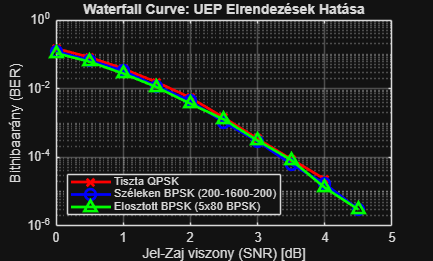


%% --- Eredmények kirajzolása ---
figure('Name', 'UEP Stratégiák Versenye', 'NumberTitle', 'off');
semilogy(snr_dB_array, ber_qpsk, 'r-x', 'LineWidth', 2, 'MarkerSize', 8); hold on;
semilogy(snr_dB_array, ber_edge, 'b-o', 'LineWidth', 2, 'MarkerSize', 8);
semilogy(snr_dB_array, ber_distr, 'g-^', 'LineWidth', 2, 'MarkerSize', 8);
grid on;
title('Waterfall Curve: UEP Elrendezések Hatása');
xlabel('Jel-Zaj viszony (SNR) [dB]');
ylabel('Bithibaarány (BER)');
legend('Tiszta QPSK', 'Széleken BPSK (200-1600-200)', 'Elosztott BPSK (5x80 BPSK)', 'Location', 'southwest');